x = linspace(-1,1,100);
f = @(x) (1 + x.^2).^(-1);
h = 1e-4;
one_sided = onesidediff(f, x, h)

one_sided =     0.5000    0.5101    0.5202    0.5302    0.5401    0.5499    0.5596    0.5690    0.5783    0.5872    0.5957    0.6039    0.6117    0.6189    0.6255    0.6315    0.6367    0.6412    0.6448    0.6474    0.6490    0.6495    0.6488    0.6468    0.6435    0.6386    0.6323    0.6244    0.6148    0.6035    0.5904    0.5754    0.5586    0.5400    0.5194    0.4969    0.4725    0.4462    0.4182    0.3884    0.3570    0.3240    0.2895    0.2537    0.2167    0.1788    0.1399    0.1004    0.0604    0.0201


true_derivative = diff(f(x))

true_derivative =     0.0102    0.0104    0.0106    0.0108    0.0110    0.0112    0.0114    0.0116    0.0118    0.0119    0.0121    0.0123    0.0124    0.0126    0.0127    0.0128    0.0129    0.0130    0.0131    0.0131    0.0131    0.0131    0.0131    0.0130    0.0130    0.0128    0.0127    0.0125    0.0123    0.0121    0.0118    0.0115    0.0111    0.0107    0.0103    0.0098    0.0093    0.0087    0.0082    0.0075    0.0069    0.0062    0.0055    0.0048    0.0040    0.0032    0.0024    0.0016    0.0008         0


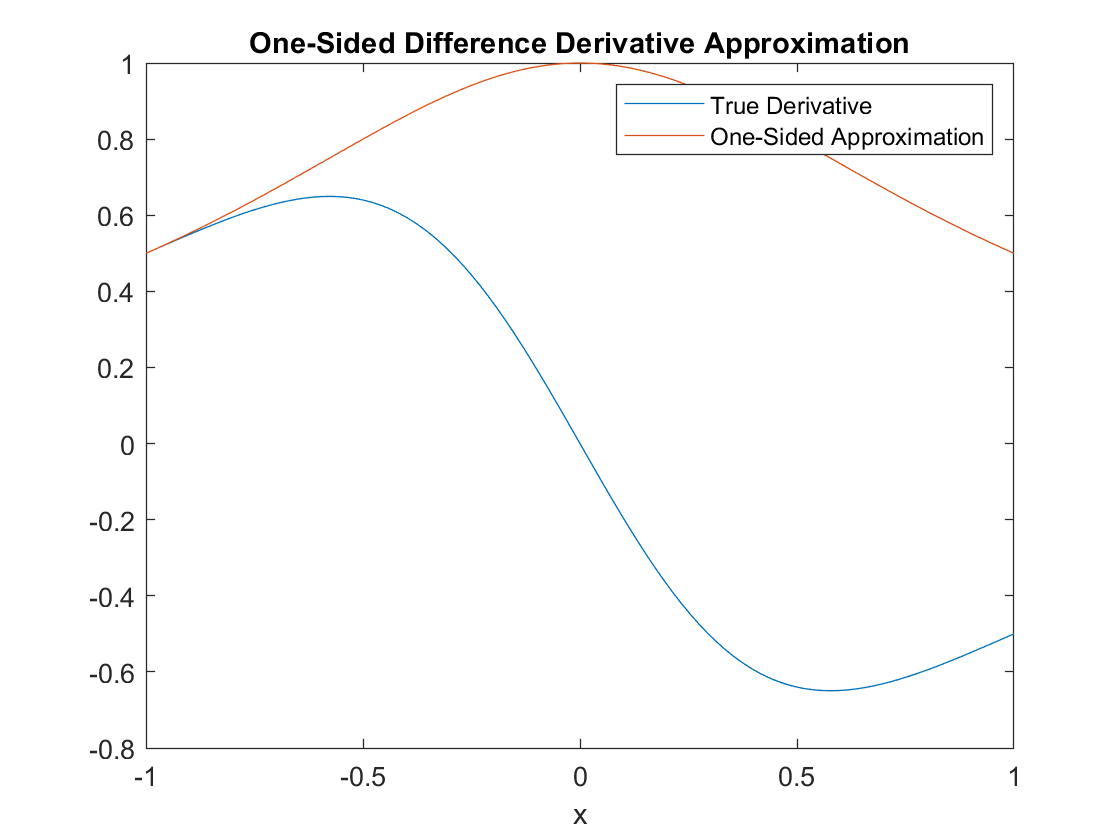

plot(x, one_sided);
hold on
plot(x, f(x));
legend('True Derivative', "One-Sided Approximation");
xlabel('x');
title("One-Sided Difference Derivative Approximation");
hold off